% Fråga 2 
disp('% Fråga 2 %')

% Fråga 2 %


disp('a) Kvalitativ data')

a) Kvalitativ data


disp('b) Nej, data saknas för flera av variablarna')

b) Nej, data saknas för flera av variablarna



% Fråga 3
disp('% Fråga 3 %')

% Fråga 3 %


disp('Histogram för vikt med fem kategorier')

Histogram för vikt med fem kategorier


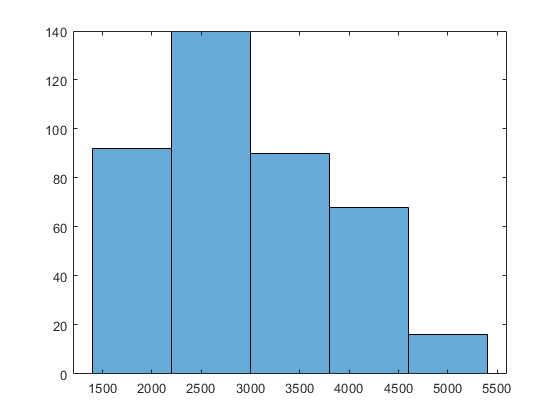

histogram(Weight,5)

disp('Lämpligt antal kategorier bör vara 5 eftersom antalet ton aldrig överstiger 6.')

Lämpligt antal kategorier bör vara 5 eftersom antalet ton aldrig överstiger 6.



% Fråga 4
disp('% Fråga 4 %')

% Fråga 4 %


disp('I ett lådagram för vikten ser vi direkt vilken spridning datan har, till skillnad')

I ett lådagram för vikten ser vi direkt vilken spridning datan har, till skillnad


disp('mot histogrammet där vi (om vi vill) kan gruppera in antal av data')

mot histogrammet där vi (om vi vill) kan gruppera in antal av data


disp('i klasser och åskådliggöra dessa efter behov.')

i klasser och åskådliggöra dessa efter behov.


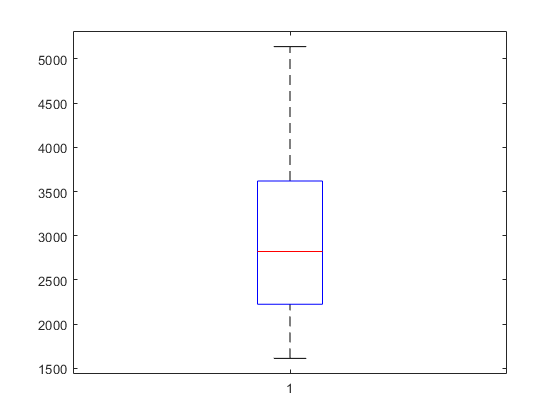

boxplot(Weight)


% Fråga 5
disp('% Fråga 5 %')

% Fråga 5 %


disp('Medianen för vikt enligt MATLAB:')

Medianen för vikt enligt MATLAB:


median(Weight)

ans = 2.8225e+03


disp('Standardavvikelsen är 847')

Standardavvikelsen är 847


std(Weight)

ans = 847.0043


% Fråga 6
disp('% Fråga 6 %')

% Fråga 6 %


weights_total = 0;
n = length(Weight);
for k=1:n
    weights_total = weights_total+Weight(k,:);
end
weights_total

weights_total = 1209642

disp('Median för vikt enl. egen funktion:')

Median för vikt enl. egen funktion:


median_weight = (weights_total/n)

median_weight = 2.9794e+03

avvikelser = 0;
for k=1:n
    avvikelser = avvikelser+((Weight(k,:)-median_weight)^2);
end
standardavvikelse_vikt = sqrt(avvikelser/n)

standardavvikelse_vikt = 845.9606

disp('Egen formel för standardavvikelsen för vikt ger ~846')

Egen formel för standardavvikelsen för vikt ger ~846


disp('MATLABS standardavvikelse för vikt ger ~847')

MATLABS standardavvikelse för vikt ger ~847


std(Weight)

ans = 847.0043


disp('Skillnaden mellan de båda är mycket liten och anledningen är troligtvis')

Skillnaden mellan de båda är mycket liten och anledningen är troligtvis


disp('pga små avrundningar som sker vid iterationen som adderar termerna.')

pga små avrundningar som sker vid iterationen som adderar termerna.


disp('Det går säkert att ordna om man ändrar en del i MATLABs inställningar.')

Det går säkert att ordna om man ändrar en del i MATLABs inställningar.



% Fråga 7
disp('% Fråga 7 %')

% Fråga 7 %


disp('Spridningsdiagram för vikt och acceleration')

Spridningsdiagram för vikt och acceleration


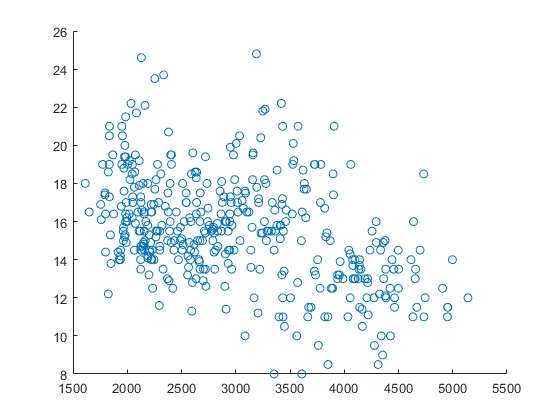

scatter(Weight,Acceleration)

disp('Vi ser att lutningen i diagrammet är negativt, vilket innebär att')

Vi ser att lutningen i diagrammet är negativt, vilket innebär att


disp('tyngre bilar har sämre acceleration än en lättare bil.')

tyngre bilar har sämre acceleration än en lättare bil.



% Fråga 8
disp('% Fråga 8 %')

% Fråga 8 %


disp('Korrelation enl. MATLAB')

Korrelation enl. MATLAB


corr(Weight, Acceleration)

ans = -0.4301

disp('Baserat på Pearsons korrelationskoefficient')

Baserat på Pearsons korrelationskoefficient


(cov(Weight,Acceleration))/(std(Weight)*std(Acceleration))

ans =   302.1391   -0.4301
   -0.4301    0.0033



disp('I vår egen funktion använder vi cov(x,y) som ger tillbaka en 2x2-matris.')

I vår egen funktion använder vi cov(x,y) som ger tillbaka en 2x2-matris.


disp('Det värde vi kan se för den parvisa kovarians som sker i 1x2 och 2x1 (-0.4301)')

Det värde vi kan se för den parvisa kovarians som sker i 1x2 och 2x1 (-0.4301)


disp('i båda kolumnerna överensstämmer med det värde som corr(x,y) ger oss.')

i båda kolumnerna överensstämmer med det värde som corr(x,y) ger oss.


disp('Värdet ska tolkas som något negativ, dvs ju tyngre bil desto sämre acceleration.')

Värdet ska tolkas som något negativ, dvs ju tyngre bil desto sämre acceleration.



disp('% Fråga 9')

% Fråga 9


disp('Tyngdkraften')

Tyngdkraften
